# Synthetic Aperture Radar

In this lab, we demonstrate the image formation process for a synthetic aperture radar (SAR). We will create a scene with multiple scatterers, simulate the return from these scatterers, and then form the image.

## Scene Definition

Let us define 9 scatterers in the scene with 1km in between along x and y directions. The scatterers are centered at 18km down range (x axis) and origin cross range (y axis). Assuming flat earth, the altitudes (z axis) of all scatterers are 0. All scatterers are static. Note that in real systems, the radar will be airborne or spaceborne. But for the purpose of illustration, we will just ignore the third dimension.

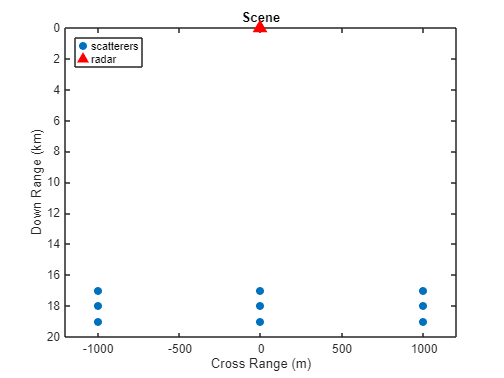

Rcrp = 18e3;
CRPPos = [Rcrp;0;0];   % center reference point
[tr,tc] = meshgrid([-1000 0 1000],[-1000 0 1000]);
Ntgt = numel(tr);
TgtPosC = [tr(:).';tc(:).';zeros(1,Ntgt)];

TgtPos = TgtPosC+CRPPos;
TgtVel = zeros(3,Ntgt);

plot(TgtPos(2,:),TgtPos(1,:)/1e3,'.','MarkerSize',20);
hold on;
plot(0,0,'r^','MarkerSize',10,'MarkerFaceColor',[1 0 0]);
hold off;
legend('scatterers','radar','Location','NorthWest')
ylim([0 20]);
xlim([-1200 1200]);
axis ij
title('Scene')
xlabel('Cross Range (m)');
ylabel('Down Range (km)');

## Radar setup

Now let us set up the radar.

Assume we want a square resolution cell with both down range and cross range resolution to be 50 meters. The maximum unambiguous range is 20 km. 

The down range resolution helps define the parameters of the waveform. Using a linear FM signal in X band, the parameters are captured below.

fc = 10e9;
c = 3e8;
lambda = c/fc;

Rmax = 20e3;
res = 50;
bw = rangeres2bw(res,c);
prf = 1/range2time(Rmax,c);
tau = 5e-6; 
fs = 5*bw;
wav = phased.LinearFMWaveform('SampleRate',fs,'SweepBandwidth',bw,...
    'PulseWidth',tau,'PRF',prf)

wav =   phased.LinearFMWaveform with properties:

                SampleRate: 15000000
     DurationSpecification: 'Pulse width'
                PulseWidth: 5.0000e-06
                       PRF: 7500
     PRFSelectionInputPort: false
            SweepBandwidth: 3000000
            SweepDirection: 'Up'
             SweepInterval: 'Positive'
                  Envelope: 'Rectangular'
     FrequencyOffsetSource: 'Property'
           FrequencyOffset: 0
              OutputFormat: 'Pulses'
                 NumPulses: 1
             PRFOutputPort: false
    CoefficientsOutputPort: false


The cross-range resolution helps define the flight path. Assume the plane is cruising at a speed of 150 m/s.

crres = 50;
Dcr = beamwidth2ap(rad2deg(crres/Rmax),lambda)/2;
v = 150;
Ta = Dcr/v;


## Radar Simulation

Now let us simulate the radar return from the scene.

Define the radar platform moving along the cross-range direction at a constant speed.

radarplat = phased.Platform([0;-Dcr/2;0],[0;v;0]);

Define the radar transmitter and receiver, as well as the propagation channel.

tx = phased.Transmitter;
rx = phased.ReceiverPreamp('NoiseMethod','Noise power','NoisePower',db2pow(-200));
chan = phased.FreeSpace('SampleRate',fs,'OperatingFrequency',fc,...
    'TwoWayPropagation',true,'PropagationSpeed',c);

The radar return is simulated using a stop and hop assumption. The return for a SAR is often referred to as phase history.

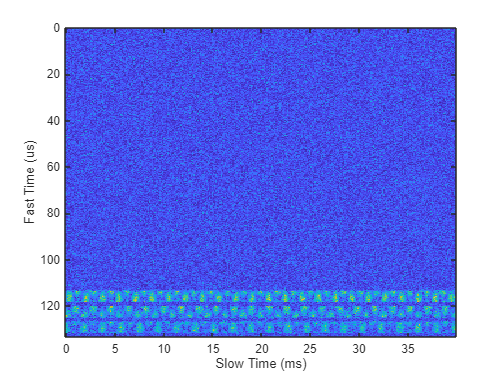

Nsampr = fs/prf;
Nsampcr = Ta*prf;
Np = Ta*prf;

PhaseHistory = zeros(Nsampr,Nsampcr)+1i*zeros(Nsampr,Nsampcr);
for m = 1:Np
    [radarpos,radarvel] = radarplat(1/prf);                         % radar, scatterers move

    x = wav();                                                      % waveform
    xt = tx(x);                                                     % transmit
    xr = chan(repmat(xt,1,Ntgt),radarpos,TgtPos,radarvel,TgtVel);   % propagate
    PhaseHistory(:,m) = rx(sum(xr,2));                              % receive

end

ftgrid = (0:Nsampr-1)/fs;
stgrid = (0:Nsampcr-1)/prf;

clf;
imagesc(stgrid*1e3,ftgrid*1e6,abs(PhaseHistory));
ylabel('Fast Time (us)');
xlabel('Slow Time (ms)');

## Image formation

The first step of image formation is down range focusing, which can be achieved by performing matched filter. In general, we know the area of interest for imaging so we can process only the range bins that correspond to our interests. In this lab, we set the minimum interested range as 16 km.

Note that after matched filtering, the processed signal is focused down range.

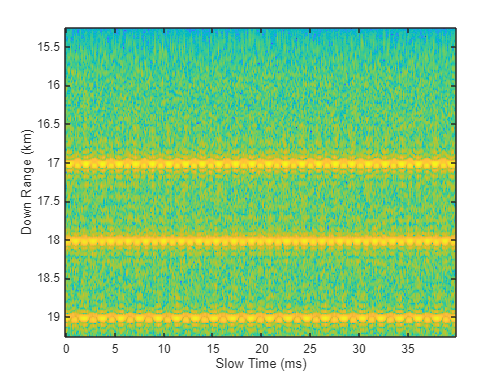

rmin = 16000;
rminidx = rmin/(c/(2*fs))+1;
PhaseHistory_process = PhaseHistory(rminidx:end,:);

mfcoeff = getMatchedFilter(wav);
mf = phased.MatchedFilter('Coefficients',mfcoeff);
yr = mf(PhaseHistory_process);
rgrid = c*ftgrid(rminidx:end)/2-(numel(mfcoeff)-1)*c/(2*fs);

imagesc(stgrid*1e3,rgrid/1e3,mag2db(abs(yr)));
ylabel('Down Range (km)');
xlabel('Slow Time (ms)');

For cross range, the focusing is achieved via Doppler domain at each range bin, thus the name Doppler beam sharpening (DBS). The scatterers can be clearly seen in the formed image.

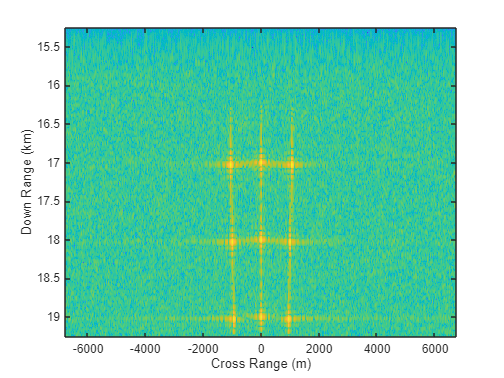

Ncrfft = 1024;
yr = fftshift(fft(yr,Ncrfft,2),2);

fdgrid = (0:Ncrfft-1)*prf/Ncrfft-prf/2;
crgrid = lambda*Rcrp*fdgrid/(2*v);

imagesc(crgrid,rgrid/1e3,mag2db(abs(yr)));
ylabel('Down Range (km)');
xlabel('Cross Range (m)');

## Interpolate cross range and range

If we look at the generated image, we can see that although all scatterers are clearly shown, they are not aligned in both down range and cross range. 

The misalignment along the cross range is related to how we map Doppler frequency to the cross range offset. The map used in the previous section is accurate only at the center of the scene. To mitigate that, we could remap the cross range at each range bin. After that, you can see that all scatterers are at the expected cross range.

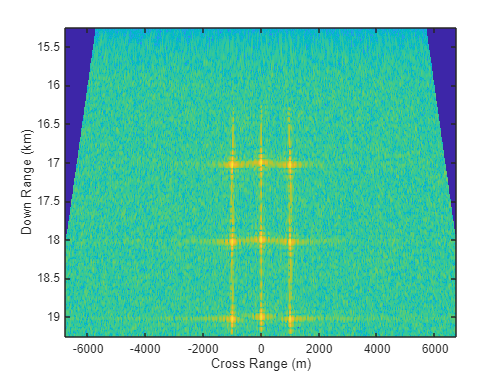

yrinterp = yr;
for m = 1:size(yr,1)
    yrinterp(m,:) = interp1(lambda*rgrid(m)*fdgrid/(2*v),yr(m,:),crgrid);
end

imagesc(crgrid,rgrid/1e3,mag2db(abs(yrinterp)));
ylabel('Down Range (km)');
xlabel('Cross Range (m)');

The distortion along range is due to the fact that the propagation takes longer to a scatterer that is off center. Since we could compute the propagation time based on the range and cross range, we can correct that as well.

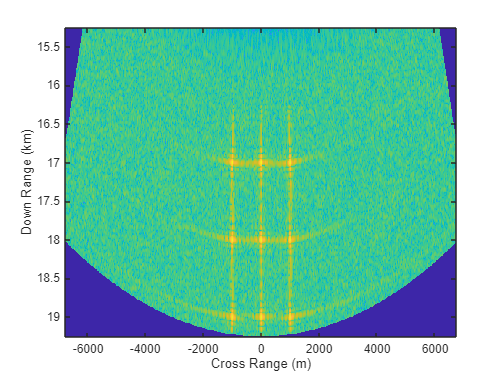

for m = 1:size(yr,2)
    yrinterp(:,m) = interp1(sqrt(rgrid.^2-crgrid(m).^2),yrinterp(:,m),rgrid);
end
imagesc(crgrid,rgrid/1e3,mag2db(abs(yrinterp)));
ylabel('Down Range (km)');
xlabel('Cross Range (m)');